# Eddy currents

Current Field Stats:
  Max speed: 0.985 m/s
  Min speed: 0.015 m/s
  Mean speed: 0.220 m/s
Starting APF path planning with wave glider dynamics in eddy current field...
Starting wave glider path planning...
Goal reached in 1102 iterations!

Wave Glider Path Statistics:
  Path length: 131.99 m
  Total time: 176.2 s (2.9 min)
  Average ground speed: 0.75 m/s
  Waypoints: 881
  Total turning: 19.29 rad (1105.1 deg)

Starting APF path planning WITHOUT current effects...
Starting wave glider path planning...
Goal reached in 729 iterations!

Wave Glider Path Statistics:
  Path length: 116.64 m
  Total time: 146.0 s (2.4 min)
  Average ground speed: 0.80 m/s
  Waypoints: 730
  Total turning: 10.92 rad (625.4 deg)

--- Wave Glider Parameters ---
Average Speed: 0.80 m/s
Turning Radius: 1.50 m
Max Turn Rate: 0.533 rad/s (30.6 deg/s)
Computation time (with currents): 0.085 s
Computation time (no currents): 0.025 s


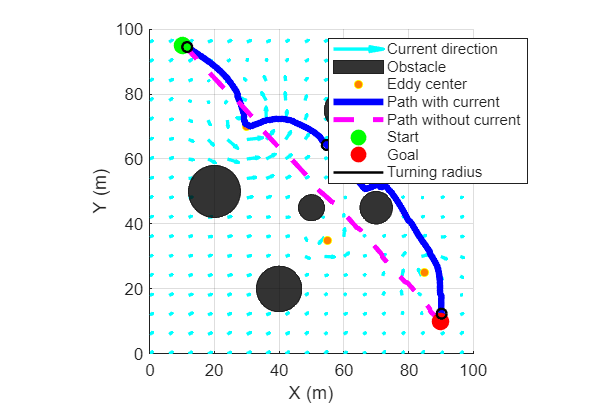

function apf_path_planning_wave_glider_eddies()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics and Complex Eddy Current Field
    % Eddy current field scenario 

    % Clear workspace
    clear; close all; clc;

    % Environment setup - 100x100m
    field_size = 100;     % Size of the field
    resolution = 2;     % Grid resolution (coarser for larger field)
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters
    start_pos    = [10, 95];
    goal_pos     = [90, 10];
    robot_radius = 1.53;

    % WAVE GLIDER DYNAMICS PARAMETERS
    wave_glider.avg_speed = 0.8;        % m/s
    wave_glider.turning_radius = 1.5;   % m
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % OBSTACLES
    obstacles = [
        20, 50, 8;
        60, 75, 6;
        40, 20, 7;
        70, 45, 5;
        50, 45, 4;
    ];

    % APF parameters
    k_att = 0.5;
    k_rep = 15;
    d0    = 20;
    dt    = 0.2;
    max_iterations = 10000;

    % Environmental current parameters
    k_env = 2;  % Weight of environmental influence

    % CREATE COMPLEX EDDY CURRENT FIELD
    [Ux, Uy] = create_eddy_current_field(X, Y);

    % Calculate potential
    U_att   = attractive_potential(X, Y, goal_pos, k_att);
    U_rep   = repulsive_potential(X, Y, obstacles, k_rep, d0);
    U_env   = environmental_potential(X, Y, Ux, Uy, k_env);
    U_total = U_att + U_rep + U_env; %#ok<NASGU>

    % WITH CURRENTS
    fprintf('Starting APF path planning with wave glider dynamics in eddy current field...\n');
    t0 = tic;
    path_with_current = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env, Ux, Uy, wave_glider);
    comp_with = toc(t0);

    % NO-CURRENT (k_env = 0, zero U/V)
    fprintf('\nStarting APF path planning WITHOUT current effects...\n');
    Ux_zero = zeros(size(Ux));
    Uy_zero = zeros(size(Uy));
    t0 = tic;
    path_no_current = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, 0, Ux_zero, Uy_zero, wave_glider);
    comp_no = toc(t0);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Print computation times
    fprintf('Computation time (with currents): %.3f s\n', comp_with);
    fprintf('Computation time (no currents): %.3f s\n', comp_no);

    % Visualization (shows both paths)
    visualize_results(X, Y, start_pos, goal_pos, obstacles, ...
        path_with_current, path_no_current, field_size, Ux, Uy, wave_glider);
end

%% EDDY CURRENT FIELD GENERATION
function [U, V] = create_eddy_current_field(X, Y)
    [ny, nx] = size(X);

    % Eddy parameters
    eddy_centers  = [30, 70; 75, 65; 55, 35; 85, 25];
    eddy_strength = [0.8, -0.6, 0.9, -0.4]; % m/s
    eddy_radius   = [25, 20, 12, 18];       % m
    eddy_decay    = [0.8, 1.2, 1.5, 0.9];

    % Background current with mild spatial variation
    U_background = 0.15; V_background = 0.08;
    U_bg_variation = 0.05 * sin(2*pi*X/100);
    V_bg_variation = 0.03 * cos(2*pi*Y/80);
    U = U_background + U_bg_variation;
    V = V_background + V_bg_variation;

    % Build eddying flow field
    for eddy = 1:4
        c = eddy_centers(eddy, :);
        S = eddy_strength(eddy);
        R = eddy_radius(eddy);
        dK = eddy_decay(eddy);

        for i = 1:nx
            for j = 1:ny
                dx = X(j,i) - c(1);
                dy = Y(j,i) - c(2);
                r = hypot(dx, dy);

                if r < R && r > 0.5
                    th  = atan2(dy, dx);
                    vel = S * (1 - (r/R)^2) * exp(-dK*r/R);
                    vel = vel * (1 + 0.2*sin(2*th)); % slight ellipticity
                    U(j,i) = U(j,i) - vel * sin(th);
                    V(j,i) = V(j,i) + vel * cos(th);
                end
            end
        end
    end

    % Light turbulent noise
    noise_strength = 0.05;
    U = U + noise_strength * (rand(size(U)) - 0.5);
    V = V + noise_strength * (rand(size(V)) - 0.5);

    % Field stats
    spd = hypot(U, V);
    fprintf('Current Field Stats:\n');
    fprintf('  Max speed: %.3f m/s\n', max(spd(:)));
    fprintf('  Min speed: %.3f m/s\n', min(spd(:)));
    fprintf('  Mean speed: %.3f m/s\n', mean(spd(:)));
end

%% Wave Glider Path Planning
function path = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, k_env, Ux, Uy, wave_glider)

    % Local minima escape parameters
    stagnation_window     = 70;
    min_improve           = 0.5;
    force_eps             = 0.05;
    escape_angle_deg      = 85;
    escape_duration_sec   = 1;
    escape_steps_default  = max(1, round(escape_duration_sec / dt));

    % State
    current_pos     = start_pos;
    current_heading = 0;
    current_speed   = wave_glider.avg_speed;
    goal_threshold  = 1;

    path     = current_pos;
    headings = current_heading;

    % Progress tracking
    dist_hist = [];
    best_dist_recent = inf;
    no_improve_steps = 0;

    % Escape state
    escape_steps_left = 0;
    escape_sign       = 1;
    escape_angle_rad  = deg2rad(escape_angle_deg);

    fprintf('Starting wave glider path planning...\n');

    for iter = 1:max_iter
        % Interpolate current at position
        c = get_current_at_position(current_pos, Ux, Uy);

        % Forces at current position
        [Fx, Fy] = calculate_forces(current_pos, goal_pos, obstacles, ...
                                    k_att, k_rep, d0, k_env, c);

        % Stagnation check
        dist_to_goal = norm(current_pos - goal_pos);
        dist_hist = [dist_hist; dist_to_goal]; %#ok<AGROW>
        if numel(dist_hist) > stagnation_window
            if (best_dist_recent - dist_to_goal) < min_improve || (hypot(Fx, Fy) < force_eps)
                no_improve_steps = no_improve_steps + 1;
            else
                no_improve_steps = 0;
            end
            best_dist_recent = min(best_dist_recent, dist_to_goal);

            if no_improve_steps >= stagnation_window || (hypot(Fx, Fy) < force_eps)
                escape_sign       = sign(randn); if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                no_improve_steps  = 0;
            end
        else
            best_dist_recent = min(best_dist_recent, dist_to_goal);
        end

        % Escape rotation if active
        if escape_steps_left > 0
            [Fx, Fy] = rotate_vec(Fx, Fy, escape_sign * escape_angle_rad);
            escape_steps_left = escape_steps_left - 1;
        end

        % Heading update with turn-rate limit
        desired_heading    = atan2(Fy, Fx);
        heading_error      = atan2(sin(desired_heading - current_heading), cos(desired_heading - current_heading));
        max_heading_change = wave_glider.max_turn_rate * dt;
        if abs(heading_error) > max_heading_change
            current_heading = current_heading + sign(heading_error) * max_heading_change;
        else
            current_heading = desired_heading;
        end
        current_heading = atan2(sin(current_heading), cos(current_heading));

        % Body -> ground velocity (add current drift)
        vx_body   = current_speed * cos(current_heading);
        vy_body   = current_speed * sin(current_heading);
        vx_ground = vx_body + c(1);
        vy_ground = vy_body + c(2);

        % Step
        next_pos = current_pos + dt * [vx_ground, vy_ground];

        % Boundary check
        if next_pos(1) < 0 || next_pos(1) > 100 || next_pos(2) < 0 || next_pos(2) > 100
            fprintf('Boundary reached at iter %d, stopping\n', iter);
            break;
        end

        % Collision check
        collision = false;
        for i = 1:size(obstacles, 1)
            oc = obstacles(i, 1:2); orad = obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path     = [path; current_pos]; %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
        else
            for turn_sign = [-1, 1]
                test_heading = current_heading + turn_sign * max_heading_change;
                test_vx = current_speed * cos(test_heading) + c(1);
                test_vy = current_speed * sin(test_heading) + c(2);
                test_pos = current_pos + dt * [test_vx, test_vy];

                test_collision = false;
                for k = 1:size(obstacles, 1)
                    oc = obstacles(k, 1:2); orad = obstacles(k, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true; break;
                    end
                end
                if ~test_collision
                    current_heading = test_heading;
                    current_pos     = test_pos;
                    path     = [path; current_pos]; %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    break;
                end
            end

            if collision
                escape_sign       = sign(randn); if escape_sign==0, escape_sign=1; end
                escape_steps_left = escape_steps_default;
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations!\n', iter);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached.\n');
    end

    % Stats
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        total_time = size(path, 1) * dt;
        avg_ground_speed = path_length / total_time;
        fprintf('\nWave Glider Path Statistics:\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s (%.1f min)\n', total_time, total_time/60);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));
        if length(headings) > 1
            dhead = diff(headings);
            dhead = atan2(sin(dhead), cos(dhead));
            total_turning = sum(abs(dhead));
            fprintf('  Total turning: %.2f rad (%.1f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

function [rx, ry] = rotate_vec(x, y, ang)
    ca = cos(ang); sa = sin(ang);
    rx = ca*x - sa*y;
    ry = sa*x + ca*y;
end

%% Helper Functions
function c = get_current_at_position(pos, Ux, Uy)
    % Nearest-neighbour interpolation on the 2 m grid
    x_idx = max(1, min(size(Ux, 2), round(pos(1)/2) + 1));
    y_idx = max(1, min(size(Ux, 1), round(pos(2)/2) + 1));
    c = [Ux(y_idx, x_idx), Uy(y_idx, x_idx)];
end

function diff = angle_diff(angle1, angle2)
    diff = angle1 - angle2;
    diff = atan2(sin(diff), cos(diff));
end

%% Potential Functions
function U_att = attractive_potential(X, Y, goal, k_att)
    U_att = k_att * ((X - goal(1)).^2 + (Y - goal(2)).^2) / 2;
end

function U_rep = repulsive_potential(X, Y, obstacles, k_rep, d0)
    U_rep = zeros(size(X));
    for i = 1:size(obstacles, 1)
        obs_x = obstacles(i, 1);
        obs_y = obstacles(i, 2);
        obs_r = obstacles(i, 3);

        d_obs = sqrt((X - obs_x).^2 + (Y - obs_y).^2) - obs_r;

        inside_mask = d_obs <= 0;
        d_obs(inside_mask) = eps;

        mask = (d_obs > 0) & (d_obs <= d0);
        U_rep(mask) = U_rep(mask) + 0.5 * k_rep * ((1./d_obs(mask)) - (1/d0)).^2;

        U_rep(inside_mask) = 1000;
    end
end

function U_env = environmental_potential(X, Y, Ux, Uy, k_env)
    U_env = -k_env * (Ux .* X + Uy .* Y);
end

%% Force Calculation 
function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0, k_env, c)
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    F_rep_x = 0; F_rep_y = 0;
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        d_center = sqrt((x - ox)^2 + (y - oy)^2);
        d_obs = d_center - orad;

        if d_obs > 0 && d_obs <= d0
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;
        elseif d_obs <= 0
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_x = F_rep_x + 100 * ux;
            F_rep_y = F_rep_y + 100 * uy;
        end
    end

    % Environmental (current) force
    F_env_x = k_env * c(1);
    F_env_y = k_env * c(2);

    % Total
    F_x = F_att_x + F_rep_x + F_env_x;
    F_y = F_att_y + F_rep_y + F_env_y;
end

%% Visualization (plots both paths)
function visualize_results(X, Y, start_pos, goal_pos, ...
    obstacles, path_with_current, path_no_current, field_size, Ux, Uy, wave_glider)

    figure('Position', [100, 100, 1200, 800]); hold on;

    % Current field arrows (subsampled)
    step = 3;
    Xs = X(1:step:end, 1:step:end);
    Ys = Y(1:step:end, 1:step:end);
    Us = Ux(1:step:end, 1:step:end);
    Vs = Uy(1:step:end, 1:step:end);

    % Avoid drawing arrows inside obstacles
    arrow_mask = true(size(Xs));
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); or = obstacles(i, 3);
        distances = sqrt((Xs - ox).^2 + (Ys - oy).^2);
        arrow_mask = arrow_mask & (distances > or);
    end

    X_arrows = Xs(arrow_mask);
    Y_arrows = Ys(arrow_mask);
    U_arrows = Us(arrow_mask);
    V_arrows = Vs(arrow_mask);

    quiver(X_arrows, Y_arrows, U_arrows*6, V_arrows*6, ...
           0.6, 'Color', [0, 1, 1, 0.4], 'LineWidth', 2, 'DisplayName', 'Current direction');

    % Obstacles
    for i = 1:size(obstacles, 1)
        cx = obstacles(i,1); cy = obstacles(i,2); cr = obstacles(i,3);
        th = linspace(0, 2*pi, 100);
        xf = cx + cr*cos(th); yf = cy + cr*sin(th);
        if i == 1
            fill(xf, yf, 'k', 'FaceAlpha', 0.8, 'DisplayName', 'Obstacle');
        else
            fill(xf, yf, 'k', 'FaceAlpha', 0.8, 'HandleVisibility','off');
        end
    end

    % Eddy centers (reference)
    eddy_centers = [30, 70; 75, 65; 55, 35; 85, 25];
    plot(eddy_centers(:,1), eddy_centers(:,2), 'yo', 'MarkerSize', 5, ...
         'MarkerFaceColor', [1, 0.5, 0], 'DisplayName', 'Eddy center');

    % Paths
     if ~isempty(path_with_current)
        plot(path_with_current(:,1), path_with_current(:,2), 'b-', 'LineWidth', 4, ...
             'DisplayName', 'Path with current');
     end

    if ~isempty(path_no_current)
        plot(path_no_current(:,1), path_no_current(:,2), 'm--', 'LineWidth', 3, ...
             'DisplayName', 'Path without current');
    end

    % Start / Goal
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor','g', 'DisplayName','Start');
    plot(goal_pos(1),  goal_pos(2),  'ro', 'MarkerSize', 10, 'MarkerFaceColor','r', 'DisplayName','Goal');

    % Sample turning-radius circles along the with-current path
    if size(path_with_current, 1) > 20
        n_circles = 3;
        circle_indices = round(linspace(10, size(path_with_current, 1)-10, n_circles));
        for idx = circle_indices
            pos = path_with_current(idx, :);
            th = linspace(0, 2*pi, 50);
            circle_x = pos(1) + wave_glider.turning_radius * cos(th);
            circle_y = pos(2) + wave_glider.turning_radius * sin(th);
            if idx == circle_indices(1)
                plot(circle_x, circle_y, 'k', 'LineWidth', 1.5, 'DisplayName', 'Turning radius');
            else
                plot(circle_x, circle_y, 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
            end
        end
    end

    % Axes & formatting
    xlabel('X (m)');
    ylabel('Y (m)');
    legend('show', 'Location', 'best');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
    set(gca, 'YDir', 'normal');
end

% Run
apf_path_planning_wave_glider_eddies();